a = readtable("D:\data.txt",'Delimiter',';');
a.Timestamp = datetime(a.Timestamp,'InputFormat','(yyyy,MM,dd,HH,mm,ss)');
a = table2timetable(a);
a.Properties.VariableNames

ans = 1×2 cell array
    {'Temperatur'}    {'Luftfeuchtigkeit'}


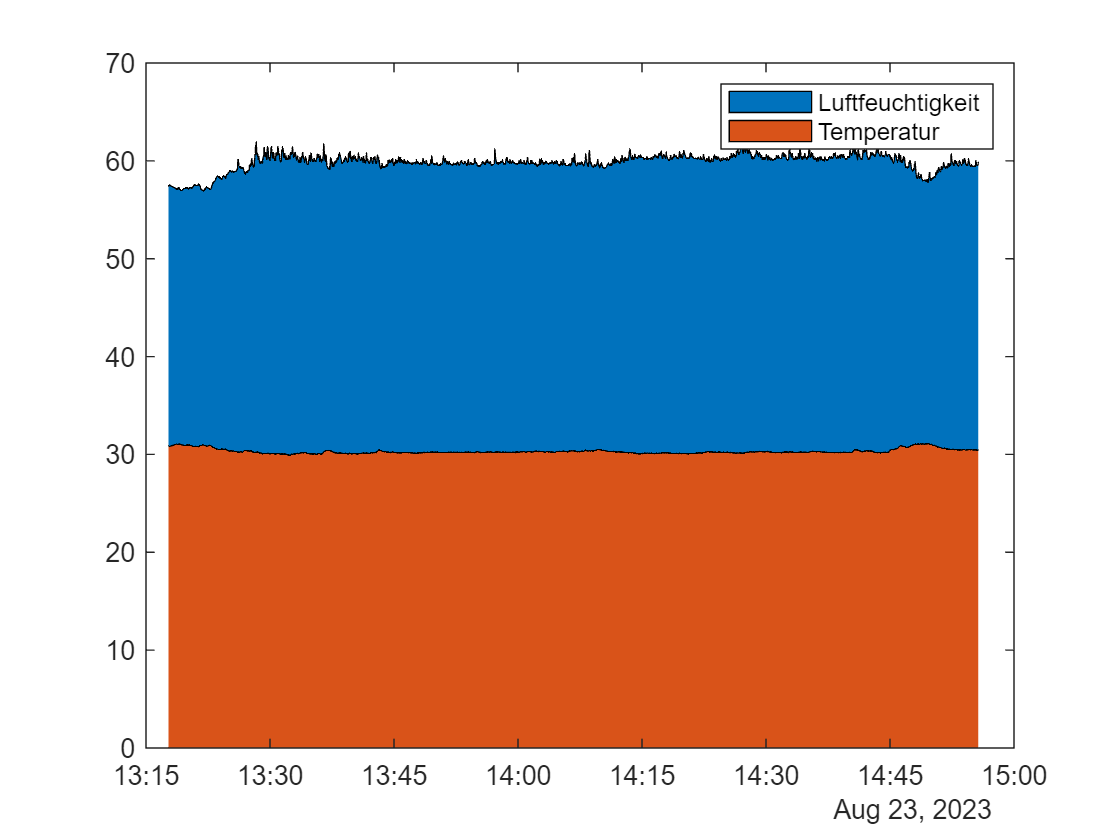


area(a.Timestamp ,a.Luftfeuchtigkeit)
hold on
area(a.Timestamp ,a.Temperatur)
legend(fliplr(a.Properties.VariableNames))